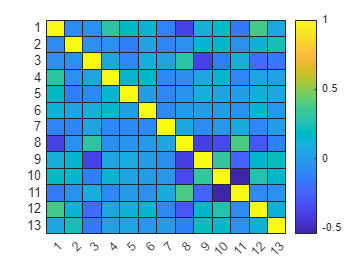


% Step 1: Import the Dataset
data = readtable('C:\\Users\\salem\\Downloads\\dataAI.csv');
data = rmmissing(data);

% Normalize numeric columns to have values between 0 and 1
for i = 1:width(data)
    if isnumeric(data{:, i})
        data{:, i} = (data{:, i} - min(data{:, i})) / (max(data{:, i}) - min(data{:, i}));
    end
end

% Initialize a logical array to mark rows with outliers
outliers = false(height(data), 1);

% Define the Z-score threshold for identifying outliers
zThreshold = 3;

% Detect and mark outliers across all numeric columns
for i = 1:width(data)
    if isnumeric(data{:, i})
        zScores = (data{:, i} - mean(data{:, i})) ./ std(data{:, i});
        outliers = outliers | (abs(zScores) > zThreshold);
    end
end

% Remove rows identified as having outliers
data(outliers, :) = [];

% Optionally, save the cleaned and processed data to a new file
writetable(data, 'C:\\Users\\salem\\Downloads\\cleaned_data.csv');

% Step 2: Read Cleaned Data and Rename Columns
data = readtable('C:\\Users\\salem\\Downloads\\cleaned_data.csv');

% Rename columns for better readability
data.Properties.VariableNames{'cp'} = 'ChestPainType';
data.Properties.VariableNames{'trestbps'} = 'RestingBloodPressure';
data.Properties.VariableNames{'chol'} = 'SerumCholestoral';
data.Properties.VariableNames{'fbs'} = 'FastingBloodSugar';
data.Properties.VariableNames{'restecg'} = 'RestingECG';
data.Properties.VariableNames{'thalach'} = 'MaxHeartRate';
data.Properties.VariableNames{'exang'} = 'ExerciseInducedAngina';
data.Properties.VariableNames{'oldpeak'} = 'STDepression';
data.Properties.VariableNames{'slope'} = 'SlopeSTSegment';
data.Properties.VariableNames{'ca'} = 'NumMajorVessels';
data.Properties.VariableNames{'thal'} = 'Thal';

% Step 3: Exploratory Data Analysis (EDA)
sum(ismissing(data));
correlationMatrix = corr(table2array(data(:, 1:end-1)));
figure;
heatmap(correlationMatrix, 'Colormap', parula, 'ColorbarVisible', 'on');

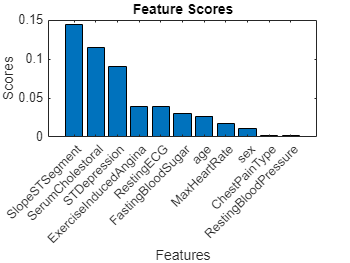





%step 6  Perform feature selection
% Check if fscmrmr function is available (requires Statistics and Machine Learning Toolbox)
if exist('fscmrmr', 'file') == 2  
    [idx, scores] = fscmrmr(X, y);  % idx - indices of features in the order of importance, scores - F-values of features

    % Plot feature scores
    figure;
    bar(scores(idx)); % Bar plot of scores in the order of importance
    set(gca, 'XTickLabel', data.Properties.VariableNames(idx), 'XTick', 1:numel(idx));
    xlabel('Features');
    ylabel('Scores');
    title('Feature Scores');
else
    error('The fscmrmr function is not available. Check the installation of the Statistics and Machine Learning Toolbox.');
end


% step 7 Remove unimportant features
X = data{:, {'age', 'sex', 'ChestPainType', 'Thal', 'ExerciseInducedAngina', 'SlopeSTSegment', 'NumMajorVessels', 'MaxHeartRate', 'STDepression'}};

% (Optional) Standardize features - not necessary for decision trees
% X = zscore(X);





% Step 8: Splitting the Data
cv = cvpartition(size(data, 1), 'HoldOut', 0.3);
X_train = X(training(cv), :);
y_train = y(training(cv));
X_test = X(test(cv), :);
y_test = y(test(cv));

 % Step 9: Model Training and Evaluation with Decision Tree
tree_mdl = fitctree(X_train, y_train);
tree_y_pred = predict(tree_mdl, X_test);
tree_accuracy = sum(tree_y_pred == y_test) / length(y_test);
fprintf('Decision Tree Accuracy: %.2f\n', tree_accuracy);

Decision Tree Accuracy: 0.97


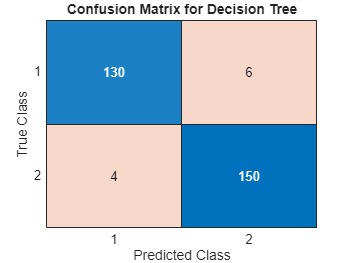

tree_confMat = confusionmat(y_test, tree_y_pred);
figure;
confusionchart(tree_confMat);
title('Confusion Matrix for Decision Tree');


% Step 10: Model Training and Evaluation with Random Forest
numTrees = 100; % Number of trees in the forest
forest_mdl = TreeBagger(numTrees, X_train, y_train, 'OOBPrediction', 'On', 'Method', 'classification');
[forest_y_pred, ~] = predict(forest_mdl, X_test);
forest_y_pred = str2double(forest_y_pred); % Convert from string to numeric
forest_accuracy = sum(forest_y_pred == y_test) / length(y_test);
fprintf('Random Forest Accuracy: %.2f\n', forest_accuracy);

Random Forest Accuracy: 1.00


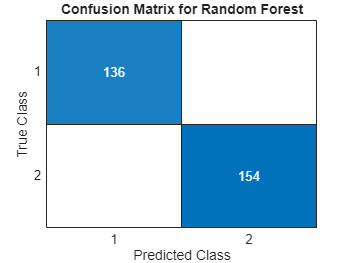

forest_confMat = confusionmat(y_test, forest_y_pred);
figure;
confusionchart(forest_confMat);
title('Confusion Matrix for Random Forest');


if istable(data)
    labels = data.(data.Properties.VariableNames{end});  % Correctly referencing the last column by name
    minority_data = data(labels == 1, :);  % Selecting rows where labels are 1
else
    minority_data = data(data(:, end) == 1, :);  % Correct for matrices, direct indexing with end
end

% step 11 Apply SMOTE assuming minority_data is now correctly set up as a matrix
% Ensure SMOTE function can handle the input as expected
function syntheticSamples = smote(data, N, k)
    % data - The minority class data samples as an MxN matrix where M is the number of samples
    % N - The percentage of SMOTE to apply
    % k - The number of nearest neighbors to use
    
    numSamples = size(data, 1);
    numFeatures = size(data, 2);
    syntheticSamples = zeros(numSamples * N, numFeatures);
    neighborIndices = knnsearch(data, data, 'K', k + 1); % find k+1 because the first one is the point itself

    for i = 1:numSamples
        for n = 1:N
            nn = randi(k) + 1; % Randomly pick one of the k nearest neighbors, +1 to skip the first neighbor (itself)
            dif = data(neighborIndices(i, nn), :) - data(i, :);
            gap = rand(1, numFeatures);
            syntheticSamples(n + (i - 1) * N, :) = data(i, :) + gap .* dif;
        end
    end
end
save('forestModel.mat', 'forest_mdl');









 